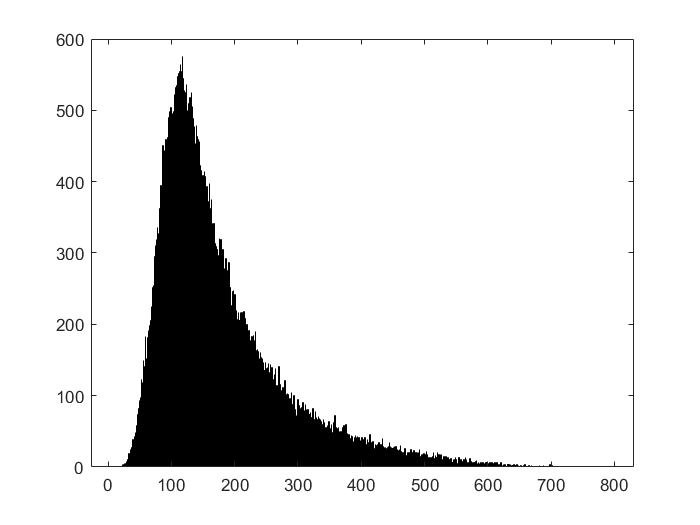

% Lab 7 - Kyle McEleney

signal = h5read("higgs_100000_pt_1000_1200.h5",'/higgs_100000_pt_1000_1200');
background = h5read("qcd_100000_pt_1000_1200.h5",'/qcd_100000_pt_1000_1200');

% 1

b_mass = background(4,:);
s_mass = signal(4,:);
total_mass = [b_mass, s_mass];

% Histogram of background mass measurement distribution
histogram(b_mass, 1000)

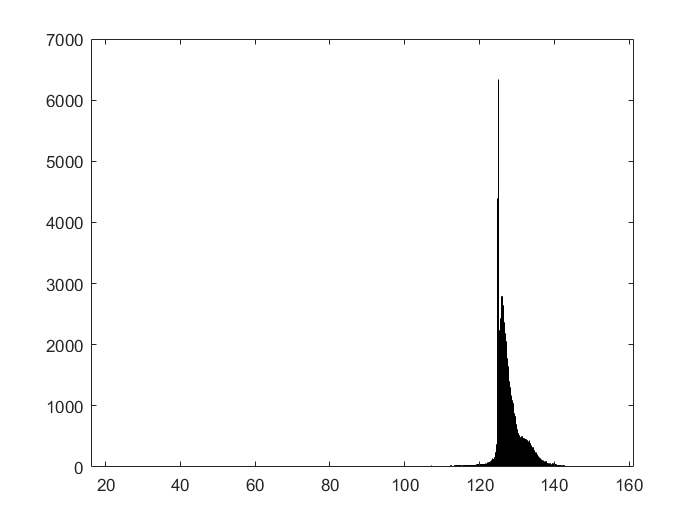

% Histogram of signal mass measurement distribution
histogram(s_mass, 1000)

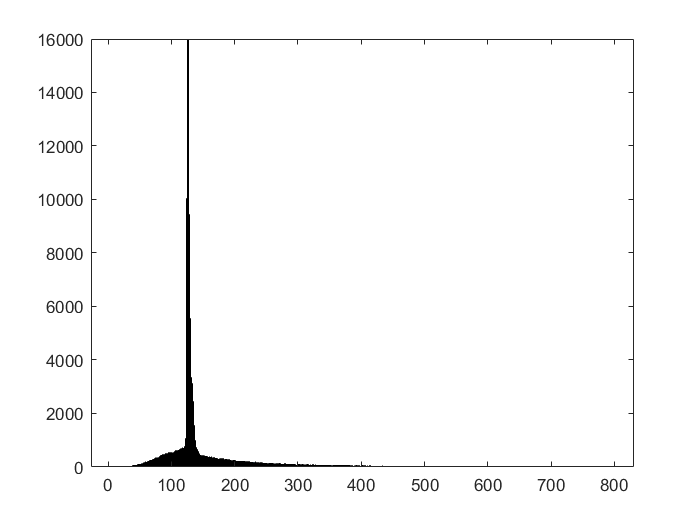


% Histogram of total mass distribution for combined dataset.
histogram(total_mass, 1000)

% Poisson statistics for significance calculation
poisson_pdf = makedist("Poisson", 'lambda', 2000);


% Expected significance without event selection for high transverse
% momentum data set using provided expected yields

% Expected yield of Higgs (signal) data set

N_higgs = 50;

% Expected yield of QCD (background) data set

N_QCD = 2000;

% Sigma value associated with the combined expected yield for the two data
% sets when compared to the pdf generated using the background set's lambda
% value (expected yield). 

significance = norminv(cdf(poisson_pdf, N_higgs+N_QCD))

significance = 1.1282

N_higgs/sqrt(N_QCD)

ans = 1.1180

% These two values are approximately similar. Since the square root of the
% lambda of a poisson distribution is equal to the standard deviation of
% the set for sufficiently large sets (which they are). 

% This may suggest that the ratio of the mean to the approximated standard deviation for the
% background acts as an approximation for the significance of the sum of
% the expected outcomes. 

% This ratio is also the inverse of the coefficient of variation which
% shows the extent of variability in relation to the mean. In this case,
% the inverse represents the significance of the the mean relative to the
% standard deviation, with higher values indicating a more reliable mean
% value (std goes down, effective mean value goes up).

% 2

% In order to optimize the expected significance, obviously insignificant
% data should be removed from the data set. Doing so will reduce the
% standard deviation significantly.

% The majority of the signal data set falls between 125 and 135 (grams?). 

% Extract data in the desireable range :

First_cut_b_mass = [];

for i = 1:length(b_mass)
    if (b_mass(1,i) < 150 & b_mass(1,i) > 120)
        First_cut_b_mass = [First_cut_b_mass, b_mass(1,i)];
    end
end

N_QCD_Mass = N_QCD * (length(First_cut_b_mass)/100000)

N_QCD_Mass = 358.7200

First_cut_s_mass = [];

for i = 1:length(s_mass)
    if (s_mass(1,i) < 150 & s_mass(1,i) > 120)
        First_cut_s_mass = [First_cut_s_mass, s_mass(1,i)];
    end
end

N_Higgs_Mass = N_higgs * (length(First_cut_s_mass)/100000)

N_Higgs_Mass = 47.9640

% Significance of the sum of the two data set Ns:
N_Higgs_Mass/sqrt(N_QCD_Mass)

ans = 2.5324

% Using this process, the set of mass cuts which will yield the highest
% significance will be the range that maximizes the number of signal datum
% and minimizes the number of the background. This could be done with a
% nested for loop which sweeps through several combinations of min/max
% discrimination values (probably just integer values) and logs the resultant significance.

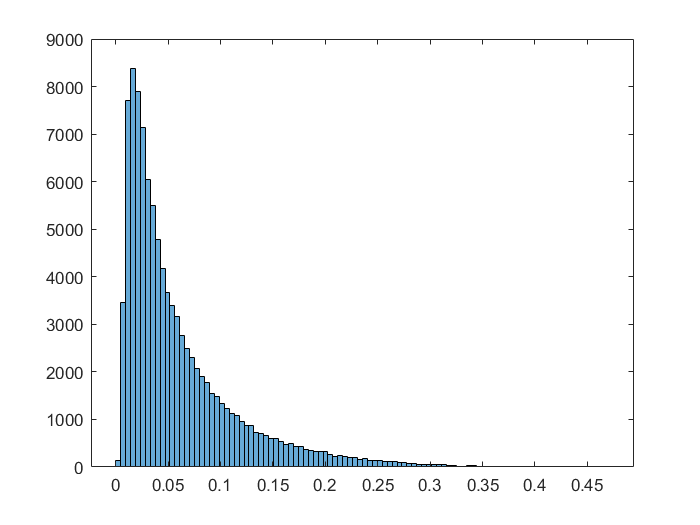


% 3 
% By looking through the plots generated in lab 5 and the analysis found
% there, it seems as though the ECF2 data set would be ideal for maximizing
% significance. This is due to the majority of the data being skewed in
% opposite directions relative to the entire data set. There are
% effectively two peaks which are to be exploited to max/min yields.


% Extract data from data sets
b_e2 = background(5,:);
s_e2 = signal(5, :);
e2_stacked = [b_e2, s_e2];

% Histogram of background data
histogram(b_e2, 100)

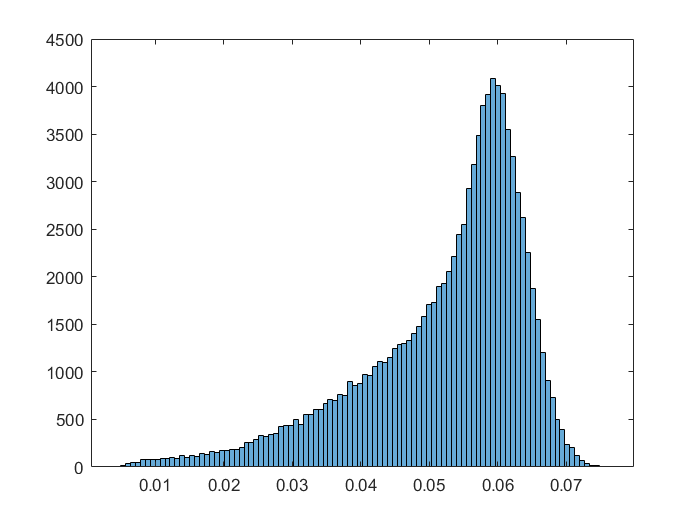


% Histogram of signal data
histogram(s_e2, 100)

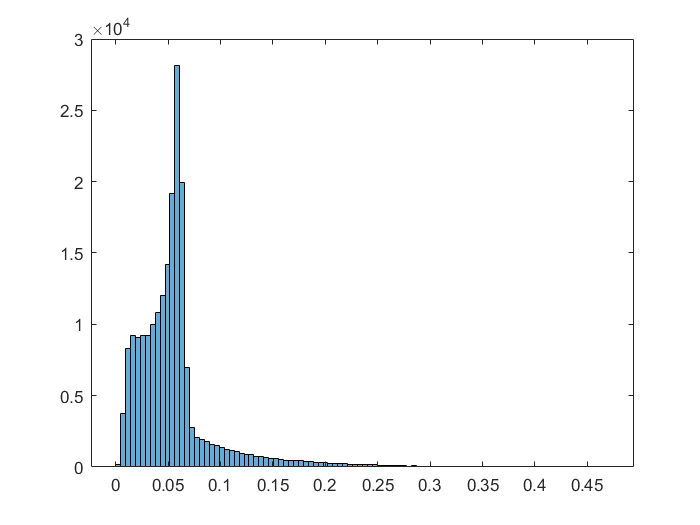

% Histogram of stacked data
histogram(e2_stacked, 100)

% This suggests that the desired range is something like 0.055-0.065

First_cut_b_e2 = [];

for i = 1:length(b_e2)
    if (b_e2(1,i) < 0.065 & b_e2(1,i) > 0.05)
        First_cut_b_e2 = [First_cut_b_e2, b_e2(1,i)];
    end
end

N_QCD_e2 = N_QCD * (length(First_cut_b_e2)/100000);
First_cut_s_e2 = [];

for i = 1:length(s_e2)
    if (s_e2(1,i) < 0.065 & s_e2(1,i) > 0.05)
        First_cut_s_e2 = [First_cut_s_e2, s_e2(1,i)];
    end
end

N_Higgs_e2 = N_higgs * (length(First_cut_s_e2)/100000)

N_Higgs_e2 = 30.0850

% Significance of the sum of the two data set Ns:
N_Higgs_e2/sqrt(N_QCD_e2)

ans = 2.1129

% While this significance is promising, additional passes may need to be
% taken with varied parameters in order to increase the significance to a
% level comparable to the mass. This is mostly due to the fact that the
% mass has such a high concentration of signal values that discrimination
% is far more effective for a small range since the disparity of data
% within the range is accentuated.


% 4 

% It seems that both my lab partner and I selected the same data set for
% discrimination, however my range of 0.05 to 0.065 fared better than his
% of .1-.2 for our respective data sets. Mine yielded a significance of
% 2.11 while his yielded 1.09.

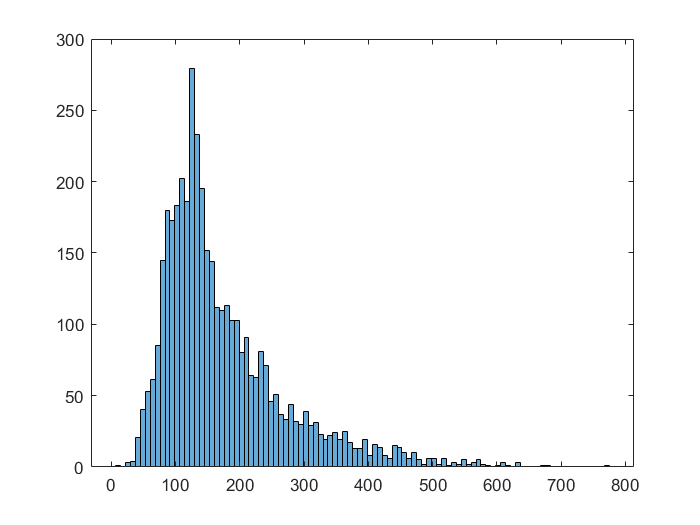

% Lab 8 - Kyle McEleney

high = h5read("data_highLumi_pt_1000_1200.h5",'/data/block0_values');
low = h5read("data_lowLumi_pt_1000_1200.h5",'/data/block0_values');

% 1 

% High luminosity - Focus on each feature of your event selection (mass)

% Extract mass data from high luminosity data set
high_mass = high(4,:);
histogram(high_mass,100);

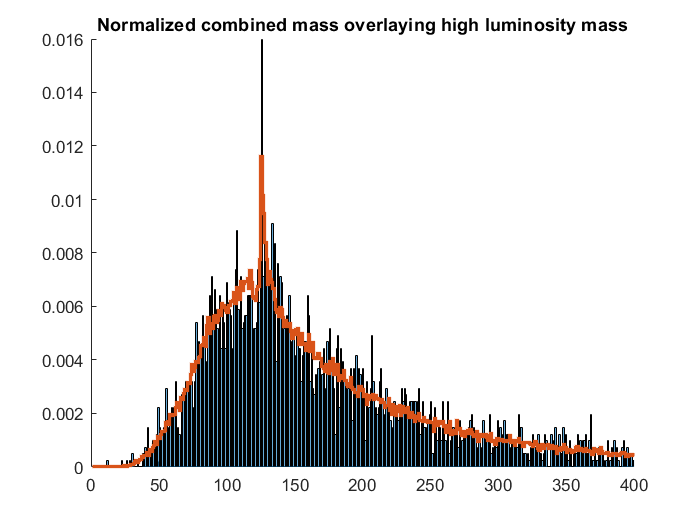

% Determine max and min values of background signal data.
b_mass_min = fix(min(b_mass));
b_mass_max = fix(max(b_mass));

% Initialize array to have sufficient buckets for all values the data takes.
discrete_counts_background = zeros(1, b_mass_max);

% Iterate through data to generate an array of counts for each discrete
% value taken.

for i = 1:length(b_mass)
    discrete_counts_background(fix(b_mass(i))) = discrete_counts_background(fix(b_mass(i))) + 1;
end

% Determine max and min values of signal data

s_mass_min = fix(min(s_mass));
s_mass_max = fix(max(s_mass));

% Initialize array to store counts of each value the signal data takes.
discrete_counts_signal = zeros(1, b_mass_max);

% Step through the signal mass array, determine how many occurances of each value are
% present.

for i = 1:length(s_mass)
    discrete_counts_signal(fix(s_mass(i))) = discrete_counts_signal(fix(s_mass(i))) + 1;
end

% Normalization of expected signal with expected background using the ratio
% of the two quantities: 2000/50 = 40. This is done in order to show an
% appreciable comparison to the total data set since the signal data is
% heavily concentrated.

normalized_discrete_counts_signal = discrete_counts_signal/40;

% Combine test data sets.
total_mass_prenormalization = discrete_counts_background + normalized_discrete_counts_signal;

% Normalize combined data sets to allow comparison to luminosity data.
normalized_combined_mass = normalize(total_mass_prenormalization, 'norm', 1);

% Generate histogram comparing test data to a profile generated by the
% simulated data. 

figure()
hold on;
histogram(high_mass,791,"Normalization",'probability');
stairs(1:791,normalized_combined_mass,"LineWidth",2)
xlim([0,400])
title("Normalized combined mass overlaying high luminosity mass");

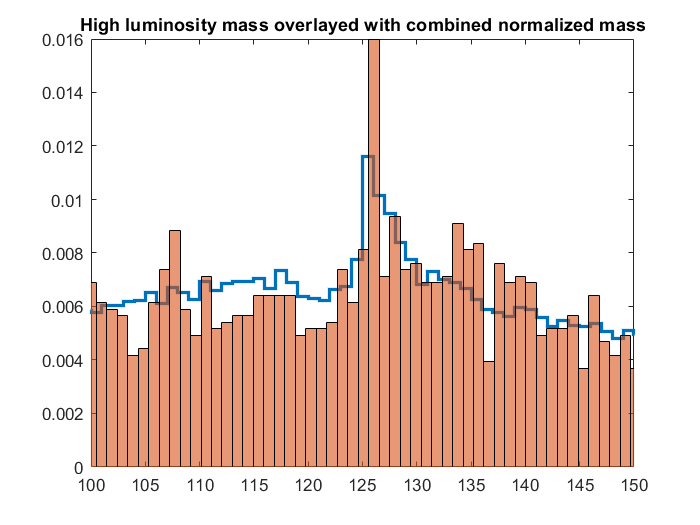

figure()
stairs(1:791,normalized_combined_mass,"LineWidth",2)
xlim([100,150])
hold on;
histogram(high_mass,791,"Normalization",'probability');
title("High luminosity mass overlayed with combined normalized mass")

% Initialize array to hold data which fulfills the discrimination test.
first_cut_high_mass = [];

% Iterate through high luminosity data to extract points of interest.
for i = 1:length(high_mass)
    if (high_mass(1,i) < 150 & high_mass(1,i) > 100)
        first_cut_high_mass = [first_cut_high_mass, high_mass(1,i)];
    end
end

% Sum of N_higgs and N_qcd
n_high = 2050;

% Determine the expected yield of the high luminosity discrimination test
n_high_mass = n_high * (length(first_cut_high_mass)/100000);

% Calculate significance of high luminosity data 
high_luminosity_sig = n_high_mass/sqrt(N_QCD_Mass)

high_luminosity_sig = 1.4677

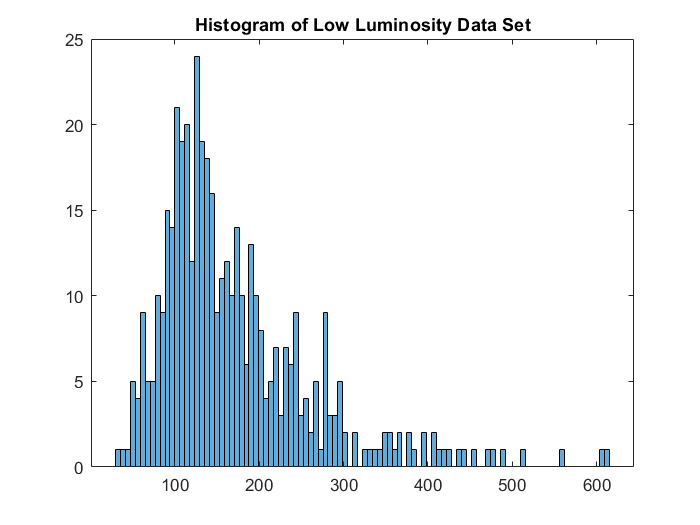

% 2 Low luminosity 

% Generate histogram of low luminosity data set
figure()
low_mass = low(4,:);
histogram(low_mass,100);
title('Histogram of Low Luminosity Data Set')

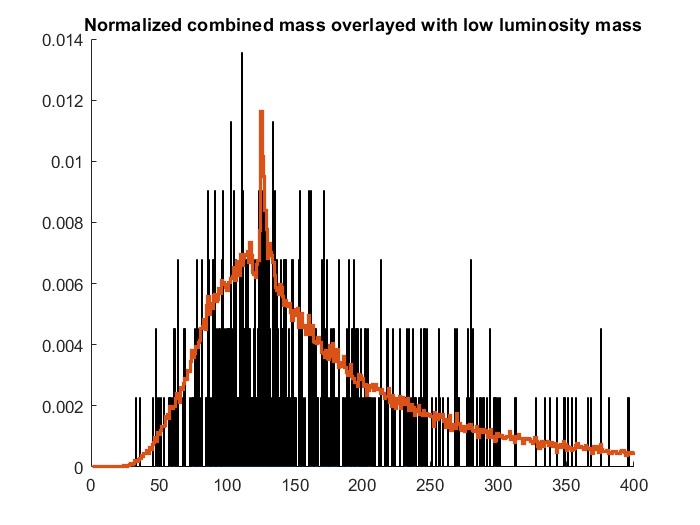

% Graph of the normalized combined mass (above) overlayed with the high
% luminosity mass (step function)

figure()
hold on;
histogram(low_mass,791,"Normalization",'probability');  
stairs(1:791,normalized_combined_mass,"LineWidth",2)
title("Normalized combined mass overlayed with low luminosity mass");
xlim([0,400])

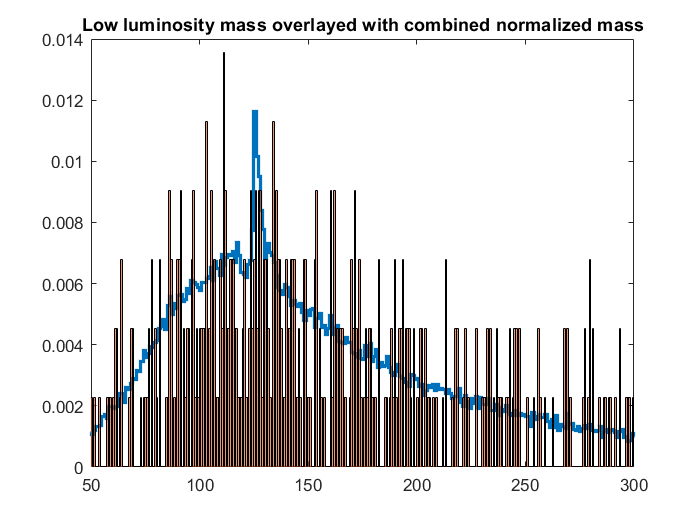

% The lower luminosity data does not fit the generated background profile
% as well as the higher luminosity data. It seems as though the peak in
% mass is closer to 100 than 150 so a lower significance is to be expected.

figure()
stairs(1:791,normalized_combined_mass,"LineWidth",2)
xlim([50,300])
hold on;
histogram(low_mass,791,"Normalization",'probability');
title("Low luminosity mass overlayed with combined normalized mass")

first_cut_low_mass = [];
for i = 1:length(low_mass)
    if (low_mass(1,i) < 275 & low_mass(1,i) > 50)
        first_cut_low_mass = [first_cut_low_mass, low_mass(1,i)];
    end
end

% Sum of N_higgs and N_qcd
n_low_mass = n_high * (length(first_cut_low_mass)/100000);
low_luminosity_sig = n_low_mass/sqrt(N_QCD_Mass)

low_luminosity_sig = 0.4124

% This is to be expected given the poor concentration of the data when
% compared to the profile the background was generated from.

% 3 

p = histcounts(low_mass,791,"Normalization",'probability');
c = 0;
i = 1;

% Iterate through the low luminosity data while the cumulative sum of the fractional
% percentage stays below 95%.

while c < 0.95
    c = c + p(i);
    i = i + 1;
end
i

i = 443

% The cumulative sum of the percentage of the data surpasses 95% at index
% 442.

low_mass(442) 

ans = 143.0776

% The observed 95% confidence level upper limit is 143.

c_e = 0;
i_e = 1;

% Iterate through the background data profile while the cumulative sum of the fractional
% percentage stays below 95%.

while c_e < 0.95
    c_e = c_e + normalized_combined_mass(i_e);
    i_e = i_e + 1;
end
i_e

i_e = 386

% The cumulative sum of the percentage of the data surpasses 95% at index
% 385.

error = abs(i_e - i)/i_e

error = 0.1477

% The error associated with the low luminosity data is 14.77%. This is to
% be expected since the low luminosity data seemed to be a poor fit with a
% significantly longer tail than the profile of the test data set which yields a low significance level. It's to
% be expected that the high luminosity data would have a lower error since
% the significance value is higher.
